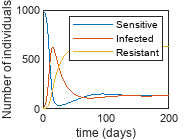

% BME 4409 Module 3 Day 1 SIRS Model sldies 17 & 18
% Author: Juan Martinez  
% Course: BME 4409 Quantitative physiology 
% Term: Spring 2022 
% J. Crayton Pruitt Family Department of Biomedical Engineering 
% University of Florida 
% Email: juanmartinez2@ufl.edu 
% September 17, 2023 


clc;clear;close all

%Parameters

rB = 3; rD = 0.02; rR = 0.05; rS = 0.01; rI = 0.0005;

odefun = @(t,y) [rB + rS*y(3) - rI*y(1)*y(2)
                 rI*y(1)*y(2) - rR*y(2) - rD*y(2)
                 rR*y(2) - rS*y(3)];
tspan = [0 200];

y0 = [990 10 0];

[t,y] = ode45(odefun,tspan,y0);

plot(t,y);
legend('Sensitive', 'Infected', 'Resistant');
xlabel('time (days)');
ylabel('Number of individuals');